# Especificações

%Projeto
Vinpk = 120;
fr = 60;
Tr = 1/fr

Tr = 0.0167

fs = 50e3;
Ts = 1/fs;
D = 0.76;
L = 2e-3;
R = 347.222;
C = 400e-6;
Dc = 1-D;
t = linspace(0,5*Ts,fs);
Vin = Vinpk*sin(2*pi*fr*t);

%% Etapa de carga do indutor - Dc
A1 = [0 0; 0 -1/(R*C)];
B1 = [1/L; 0];
C1 = [0 1];
E1 = 0;

%% Etapa de descarga do indutor - D
A2 = [0 -1/L; 1/C -1/(R*C)];
B2 = [1/L; 0];
C2 = [0 1];
E2 = 0;

A = A1*Dc + A2*D;
B = B1*Dc + B2*D;
C = C1*Dc + C2*D;
E = 0;

s = tf('s');
z = tf('z',Ts);
[num,den] = ss2tf(A,B,C,D)

num = 	1.0e+06 *

    0.0000    0.0000    1.4987


den = 	1.0e+05 *

    0.0000    0.0001    7.2200


Gp = tf(num,den)


Gp =
 
  0.76 s^2 + 5.472 s + 1.499e06
  -----------------------------
      s^2 + 7.2 s + 7.22e05
 
Continuous-time transfer function.



Gp_z = c2d(Gp,Ts,'zoh')


Gp_z =
 
  0.76 z^2 - 1.519 z + 0.7601
  ---------------------------
      z^2 - 2 z + 0.9999
 
Sample time: 2e-05 seconds
Discrete-time transfer function.



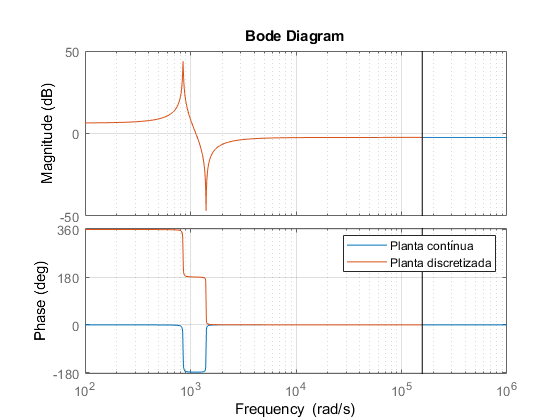


figure(1)
bode(Gp)
hold on
bode(Gp_z)
grid on
legend('Planta contínua','Planta discretizada')
hold off

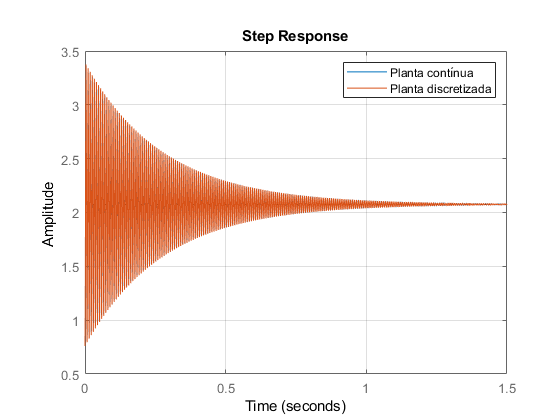


figure(2)
step(Gp)
hold on
step(Gp_z)
grid on
legend('Planta contínua','Planta discretizada')
hold off

## Filtro Anti-Aliasing

fo = 5e3;
wo = 2*pi*fo;
H = tf([wo],[1 wo])


H =
 
    3.142e04
  ------------
  s + 3.142e04
 
Continuous-time transfer function.



Hz = c2d(H,Ts,'tustin')


Hz =
 
  0.2391 z + 0.2391
  -----------------
     z - 0.5219
 
Sample time: 2e-05 seconds
Discrete-time transfer function.



## Controlador

Cz = 4.9536e-06*(z+1)^2/(z-1)


Cz =
 
  4.954e-06 z^2 + 9.907e-06 z + 4.954e-06
  ---------------------------------------
                   z - 1
 
Sample time: 2e-05 seconds
Discrete-time transfer function.



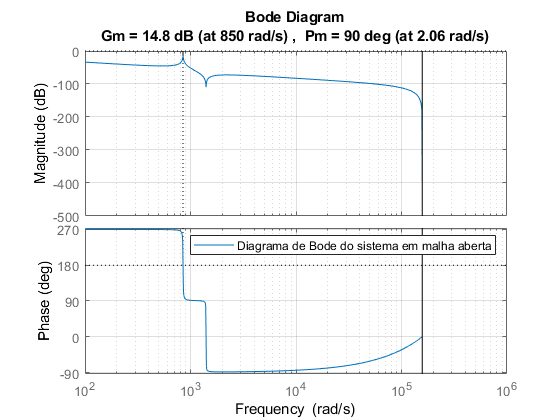


% Plantas
Gma = Gp_z*Cz;
Gmf = Gma/(1+Gp_z*Cz*Hz);

figure(3)
margin(Gp_z*Cz)     % Margem de ganho e fase do sistema em malha aberta
grid
legend('Diagrama de Bode do sistema em malha aberta')

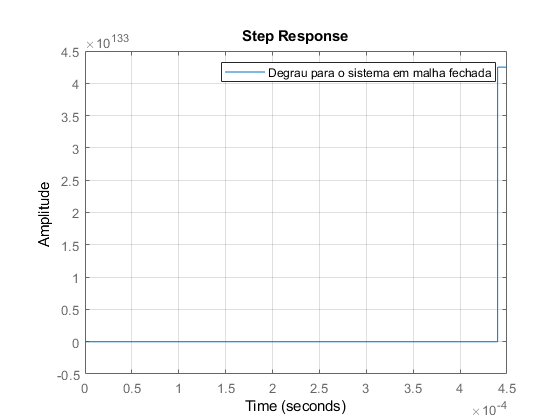


figure(4)
step(Gmf)           % Resposta ao degrau do sistema em malha fechada
grid
legend('Degrau para o sistema em malha fechada')